clear, clc
syms x L real % symbolic variable
P = inline('[1 x x^2 x^3]') % third order polynomial


P =

     Inline function:
     P(x) = [1 x x^2 x^3]



dP = inline(diff(P(x))) % symbolic derivation


dP =

     Inline function:
     dP(x) = [0.0,1.0,x.*2.0,x.^2.*3.0]



Pn = [ P(0); dP(0); P(L) ; dP(L) ] % Nodes evaluation

$$Pn = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 1 & L & L^{2} & L^{3}\\ 0 & 1 & 2\,L & 3\,L^{2} \end{array}\right)$$

N = inline(( P(x) * inv(Pn))) % Shape Functions


N =

     Inline function:
     N(L,x) = [1.0./L.^2.*x.^2.*-3.0+1.0./L.^3.*x.^3.*2.0+1.0,x-(x.^2.*2.0)./L+1.0./L.^2.*x.^3,1.0./L.^2.*x.^2.*3.0-1.0./L.^3.*x.^3.*2.0,-x.^2./L+1.0./L.^2.*x.^3]



dN = inline((dP(x) * inv(Pn))) % Derivatives


dN =

     Inline function:
     dN(L,x) = [1.0./L.^2.*x.*-6.0+1.0./L.^3.*x.^2.*6.0,(x.*-4.0)./L+1.0./L.^2.*x.^2.*3.0+1.0,1.0./L.^2.*x.*6.0-1.0./L.^3.*x.^2.*6.0,(x.*-2.0)./L+1.0./L.^2.*x.^2.*3.0]



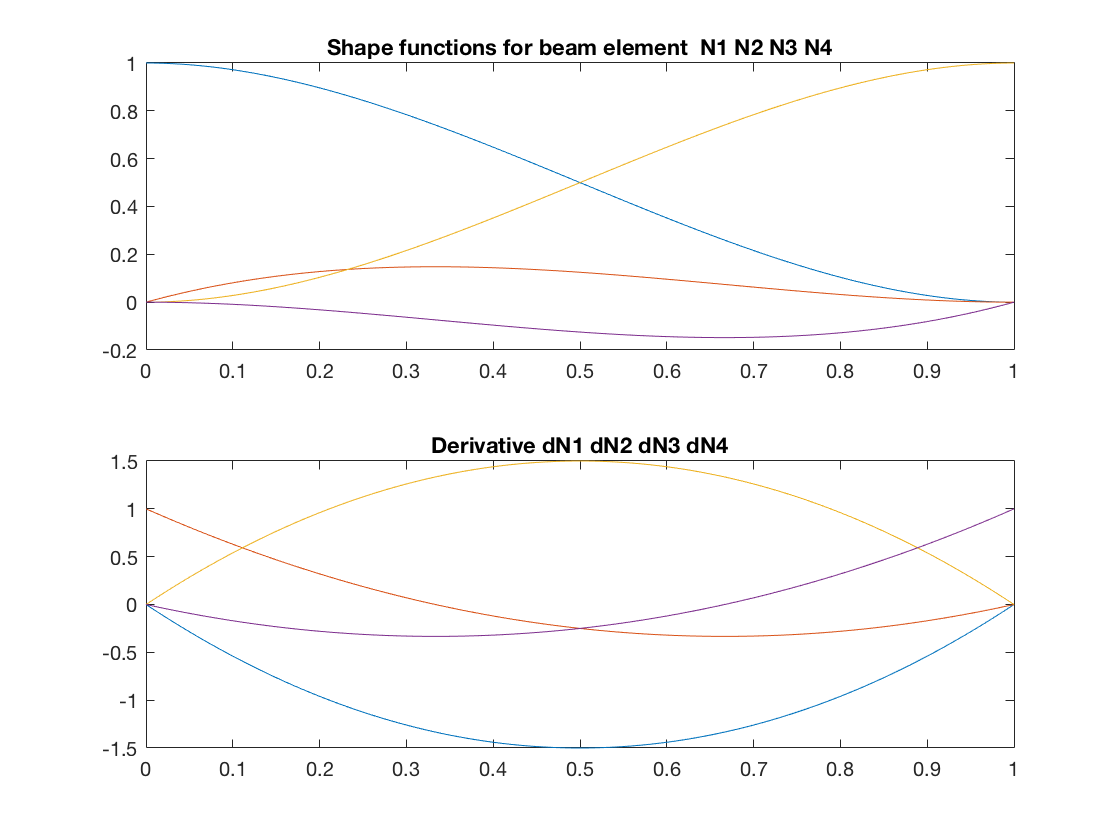

                                   
% graphs
  x = 0:0.01:1;
  subplot(2,1,1), plot(x, N(1,x')), title(' Shape functions for beam element  N1 N2 N3 N4 ')
  subplot(2,1,2), plot(x,dN(1,x')), title(' Derivative dN1 dN2 dN3 dN4 ')